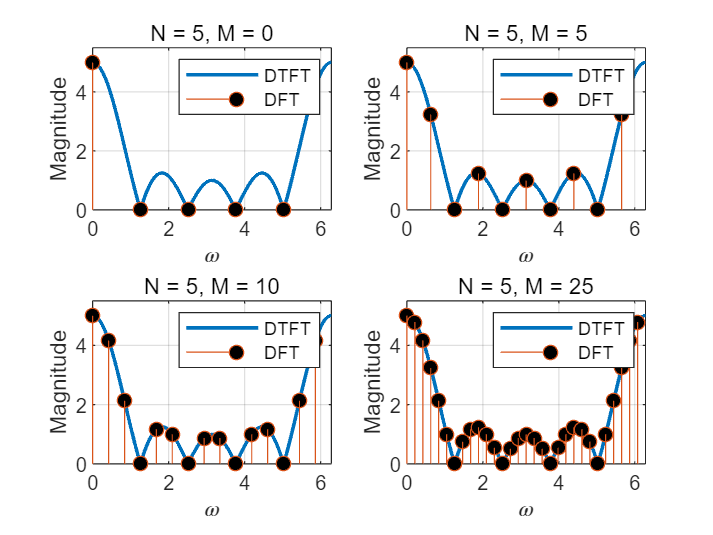

% 设定矩形序列长度N
N = 5; 
% 定义不同的补零数量M
M_values = [0, 5, 10, 25]; 

for i = 1:length(M_values)
    M = M_values(i);
    % 生成N点矩形序列
    n = 0:N - 1;
    x = ones(1, N); 
    % 补零后的序列长度
    L = N + M; 
    % 计算DTFT
    w = linspace(0, 2*pi, 1000); % 频率点，用于近似DTFT
    X_dtft = zeros(size(w));
    for k = 1:length(w)
        X_dtft(k) = sum(x.* exp(-1j * w(k) * n));
    end
    % 计算DFT
    X_dft = fft(x, L); 
    % 绘制幅度谱
    subplot(2, 2, i);
    plot(w, abs(X_dtft), 'LineWidth', 1.5);
    hold on;
    stem((0:L - 1)*2*pi/L, abs(X_dft), 'filled', 'MarkerFaceColor', 'black');
    xlabel('\omega');
    ylabel('Magnitude');
    title(sprintf('N = 5, M = %d', M));
    legend('DTFT', 'DFT');
    grid on;
    axis([0, 2*pi, 0, max(max(abs(X_dtft)), max(abs(X_dft)))*1.1]);
end